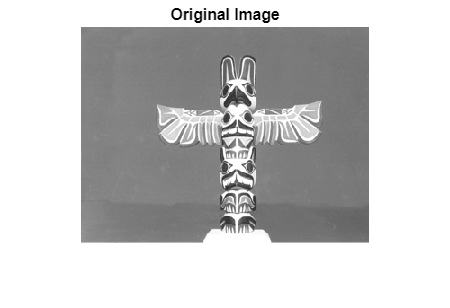

clc; 
clear; 
close all;

% Read input image
img = imread('totem.tif');
img = im2double(img); % Convert to double for processing

% Resize the original image (reduce to 50% of original size)
resized_img = imresize(img, 0.5);

% Display the resized original image
figure;
imshow(resized_img);
title('Original Image');

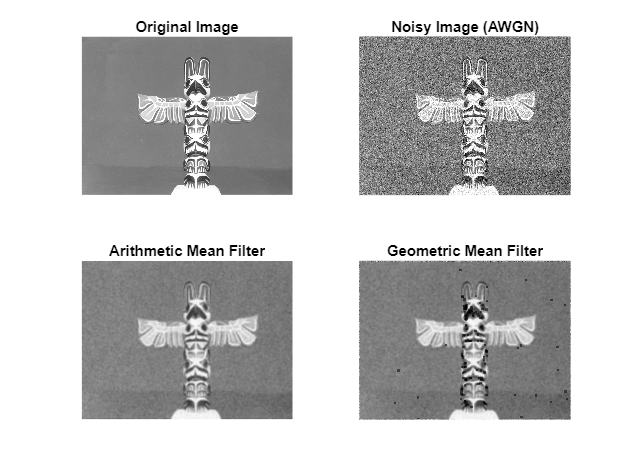


% Add AWGN noise with zero mean and variance 1000
variance = 1000 / 255^2; % Normalize for 8-bit image scale
noisy_img = imnoise(img, 'gaussian', 0, variance);

% Apply Arithmetic Mean Filter (7x7)
h = fspecial('average', [7 7]);
arithmetic_filtered = imfilter(noisy_img, h, 'replicate');

% Apply Geometric Mean Filter (7x7)
[M, N] = size(noisy_img);
geo_filtered = noisy_img;

for i = 4:M-3
    for j = 4:N-3
        patch = noisy_img(i-3:i+3, j-3:j+3);
        geo_filtered(i, j) = exp(mean(log(patch(:) + eps))); % Prevent log(0)
    end
end

% Display results
figure;
subplot(2,2,1); imshow(img); title('Original Image');
subplot(2,2,2); imshow(noisy_img); title('Noisy Image (AWGN)');
subplot(2,2,3); imshow(arithmetic_filtered); title('Arithmetic Mean Filter');
subplot(2,2,4); imshow(geo_filtered); title('Geometric Mean Filter');